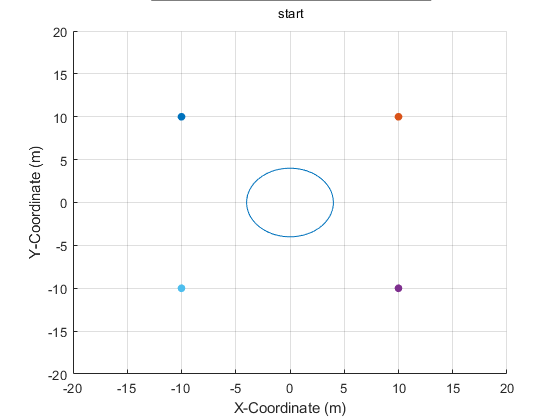

Error using ginput
Interrupted by figure deletion

clear

%Setup figure
grid on
hold on
limit = [-20 20];
axis([limit limit]);
xlabel('X-Coordinate (m)');
ylabel('Y-Coordinate (m)');

%Draw circle
syms x y
c = x^2 + y^2 == 4^2;
fimplicit(c)

%Initialize obstacles
P1 = P;
O(1) = obstacle(P1, limit);
P1.y = -10;
O(2) = obstacle(P1, limit);
P1.x = -10;
O(3) = obstacle(P1, limit);
P1.y = 10;
O(4) = obstacle(P1, limit);

%Text at the top of the figure
Gtext = annotation('textbox', [0.27 1 0.5 0], 'string', 'start', 'HorizontalAlignment','center');

% a = 208;
% D = 10;

z = zeros(1, 4);
% r = -20 + (20+20).*rand(100, 2);
% angle = 359.*rand(100, 1);
% distance = 20.*rand(100, 1);

for j = 1:100
    [P1.x, P1.y] = ginput(1);
%     P1.x = r(j,1);
%     P1.y = r(j,2);
%     P1 = eulToCar(angle(j), distance(j));
    
    for i = 1:4
        z(i) = O(i).checkClosest(P1, 1);
    end
    [~, zidx] = min(z);
    O(zidx) = O(zidx).newPoint(P1, 1);
    for i = 1:4
        if O(i).warning
            Gtext.String = 'Collision course';
            break;
        else
            Gtext.String = 'Safe';
        end
    end
end